# Part A)

## i)

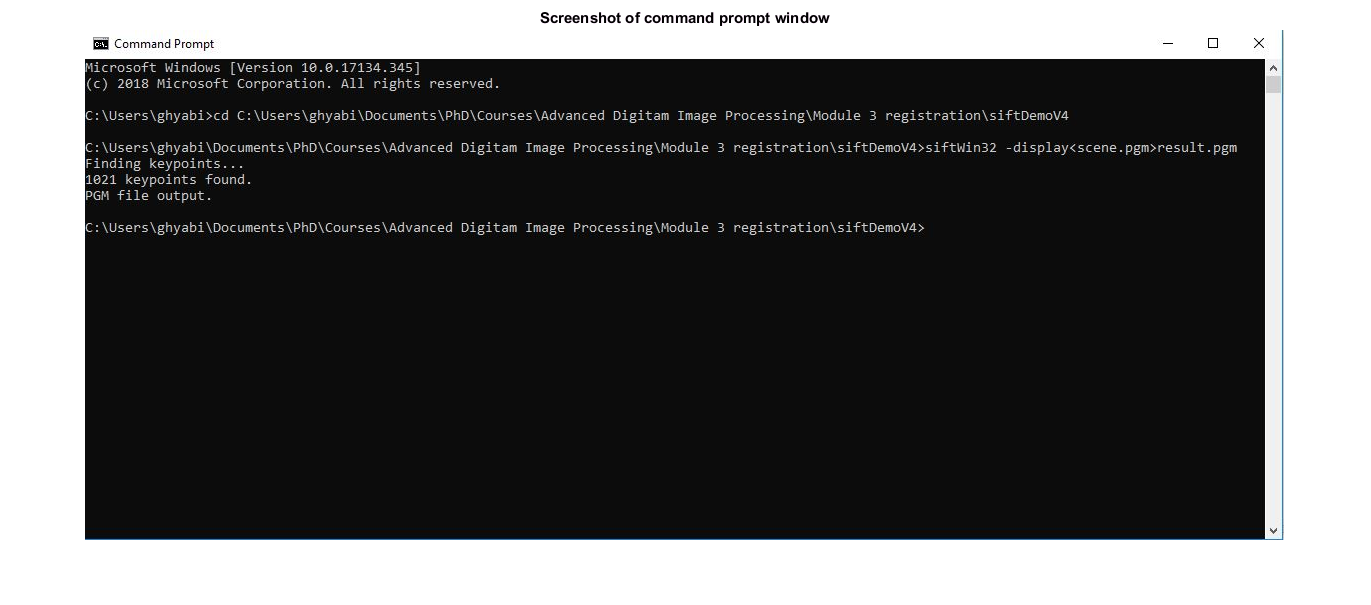

I1=double(imread('a i screenshot.jpg'))/255;
figure
imshow(I1)
title('Screenshot of command prompt window')

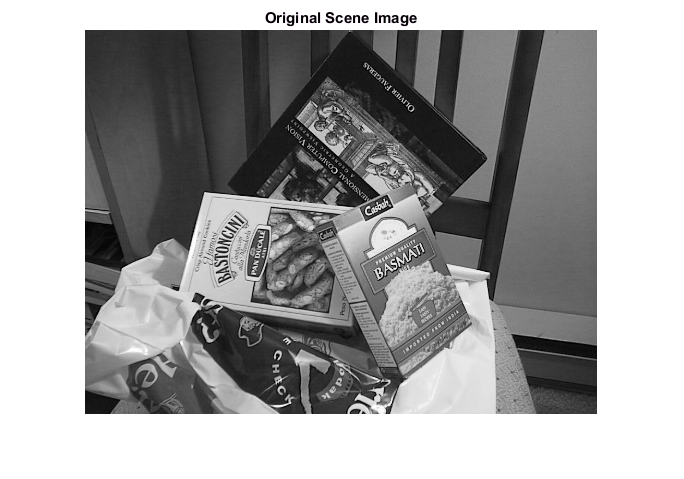


I2=double(imread([cd '\siftDemoV4\scene.pgm']))/255;
figure
imshow(I2)
title('Original Scene Image')

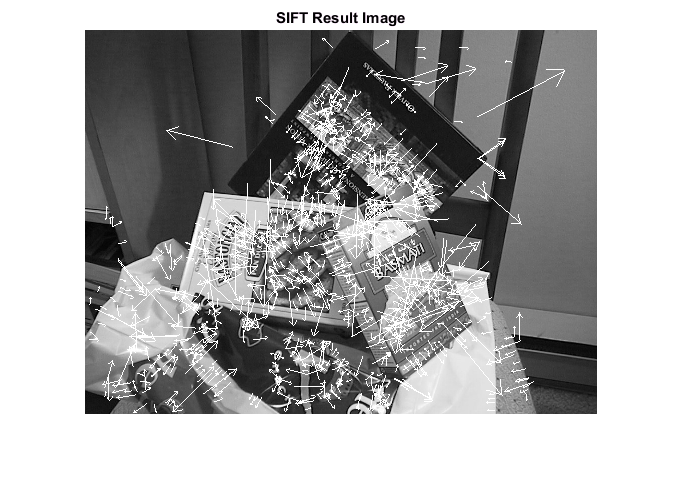


I3=double(imread([cd '\siftDemoV4\result.pgm']))/255;
figure
imshow(I3)
title('SIFT Result Image')

## ii)

system('siftDemoV4\siftWin32 -display<scene.pgm>result.pgm')

Finding keypoints... 
1021 keypoints found. 
PGM file output. 


ans = 0


I=double(imread('result.pgm'))/255;
figure
imshow(I)
title('SIFT Result Image')

## iii)

system('siftDemoV4\siftWin32 <scene.pgm>result.key')

Finding keypoints... 
1021 keypoints found. 


ans = 0

%reading first nine lines of the result file
fID=fopen('result.key');
C1=fscanf(fID,'%d',[1 2]);
C2=fscanf(fID,'%f',[1 4]);
C3=fscanf(fID,'%d',[6 20]);
C4=fscanf(fID,'%d',[1 8]);
fclose(fID);
%converting to string
C1=num2str(C1);
C2=num2str(C2);
C3=num2str(C3);
C4=num2str(C4);
%concatenating into one matrix
n=[size(C1,2);size(C2,2);size(C3,2);size(C4,2);];

C=[[C1 repmat(' ',1,max(n)-n1)];[C2 repmat(' ',1,max(n)-n2)];[C3 repmat(' ',1,max(n)-n3)];[C4 repmat(' ',1,max(n)-n4)]];

disp('The first nine lines of "result.key":' )

The first nine lines of "result.key":


disp(C)

1021   128                                                                                      
194.29        389.65         25.42        -2.259                                                
0    0    4    2   35   16   17   29  123    1   19   18   82    0    5   12    0    6   61   95
0    0   14    1   22  123    4  123  104   42    1  101   10   37    2   55    0    5    0   22
0    3    5    0   25    0    0   19   25   44    0   37    7  123    2  105    4  122    0    2
0    2    2   31    1    0    0    6   13   49   21    9   98   47  123    6   77   27    4    0
1    2   47   64    0    6   18    0    0  112    0   10   65   16   20    2   42    3  102    0
2    4    8  123    0   68   21    3    0   37    0    5    5    6    8   18    2   47   95   15
17  53  50  35  32   3  14  12                                                                  


## iv)

I=double(imread([cd '\siftDemoV4\scene.pgm']))/255;
res=[1 2 4 8 16 32]';
N=nan(6,1);
for i=1:6
    %decimating the image
    I1=imresize(I,size(I)/res(i));
    imwrite(I1,'Image.pgm')
    system('siftDemoV4\siftWin32 <Image.pgm>result.key')
    %reading number of keypoints
    fID=fopen('result.key');
    N(i)=fscanf(fID,'%d',[1 1]);
    fclose(fID);
end

Finding keypoints... 
1021 keypoints found. 


ans = 0

Finding keypoints... 
398 keypoints found. 


ans = 0

Finding keypoints... 
122 keypoints found. 


ans = 0

Finding keypoints... 
48 keypoints found. 


ans = 0

Finding keypoints... 
4 keypoints found. 


ans = 0

Finding keypoints... 
0 keypoints found. 


ans = 0

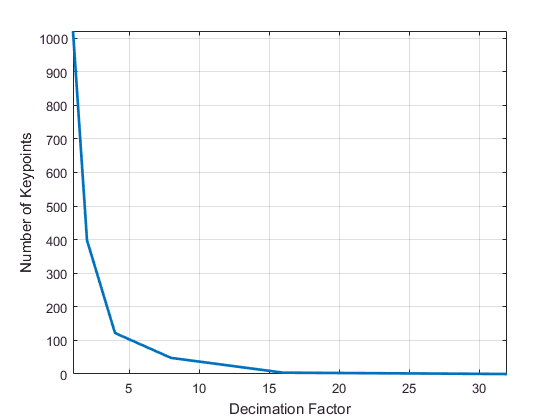


figure
plot(res,N,'LineWidth',2)
grid on
axis tight
xlabel('Decimation Factor')
ylabel('Number of Keypoints')

Number of keypoints decreases as the decimation factor is increased. This plot looks like the positive part of a reciprocal function.

## v)

system('siftDemoV4\siftWin32 <scene.pgm>result.key')

Finding keypoints... 
1021 keypoints found. 


ans = 0

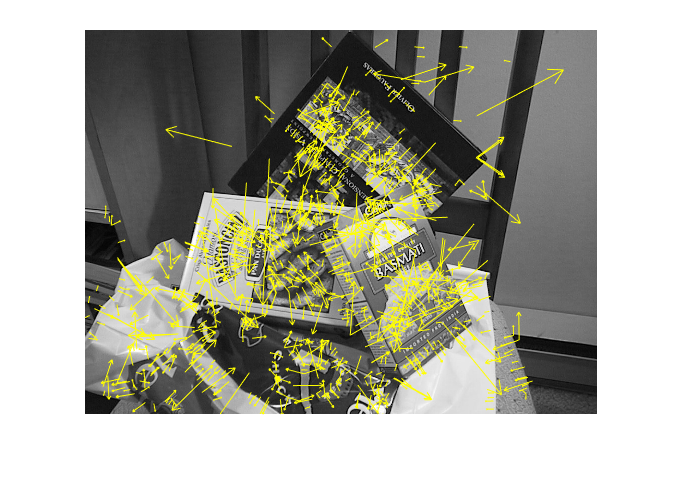

I=double(imread([cd '\siftDemoV4\scene.pgm']))/255;
fID=fopen('result.key');
N=fscanf(fID,'%d',[1 2]);
N=N(1);
Data=nan(N,4);
%reading xyso from text file and storing it in a matrix
for i=1:N
    Line=fscanf(fID,'%f',[1 4]);
    Data(i,:)=Line;
    fscanf(fID,'%d',[1 128]);
end
fclose(fID);
%defining amplification factor and arrowline angle for displaying vectors
AmpFactor=6;
ArrowAngle=7*pi/6;
%end nodes and arrow nodes
x2y2=[Data(:,1)+AmpFactor*Data(:,3).*cos(Data(:,4)+pi/2) Data(:,2)+AmpFactor*Data(:,3).*sin(Data(:,4)+pi/2)];
x3y3=[x2y2(:,1)+Data(:,3).*cos(Data(:,4)+pi/2+ArrowAngle) x2y2(:,2)+Data(:,3).*sin(Data(:,4)+pi/2+ArrowAngle)];
x4y4=[x2y2(:,1)+Data(:,3).*cos(Data(:,4)+pi/2-ArrowAngle) x2y2(:,2)+Data(:,3).*sin(Data(:,4)+pi/2-ArrowAngle)];

figure
imshow(I)
hold on
for i=1:N
   line([Data(i,2) x2y2(i,2)], [Data(i,1) x2y2(i,1)],'color','y')
   line([x3y3(i,2) x2y2(i,2)], [x3y3(i,1) x2y2(i,1)],'color','y')
   line([x4y4(i,2) x2y2(i,2)], [x4y4(i,1) x2y2(i,1)],'color','y')
end